clc
clear;

%%%%%%SELECT OPTIONS:
problem_num = 2;
diff_opt = "forward"; %{forward, backward, centered}
partition_opt = "full"; %{full, partition}

%%%%%%SET UP NEURAL NETWORK
num_outputs = 3;
occurences = 1000;

%(1) Set up initial conditions and solve ODE:
function [C, t, h, arraySize] = probsetup(problem_num, occurences)
    if problem_num == 1
        c0 = [4.0; 1.0; 0.5; 0.0]; %initial condition
        tspan = linspace(0, 2, occurences); %constant time step
        h = 2/occurences;
        arraySize = [24 12 1];
        
        k1 = 5.7; k2 = 6.1; 
        dCdt = @(t, C) [ %setup ODE
            -k1 * C(1)
             k2 * C(1) - k2 * C(2)
             k2 * C(2)
             k1 * C(1) + k2 * C(2)
        ];
    elseif problem_num == 2
        c0 = [10.0; 5.0; 1.0]; %initial condition
        tspan = linspace(0, 1, occurences); %constant time step
        h = 1/occurences;
        arraySize = [18 10];
        
        dCdt = @(t, C) [ %setup ODE
            (C(1) + 0.25) - sin(C(3))
            0.5 - C(2) * cos(C(1))
            C(1)^2 + sin(C(3))
        ];
    end %if 
    %[t, C] = ode45(dCdt, tspan, c0); %solve ODE
    [t, C] = ode15s(dCdt, tspan, c0); %solve ODE
end %function 

%(2) Calculate dX/dt
function [Xout, dXdt, dt] = diffmethod(Xin, t, h, diff_opt)
    if diff_opt == "forward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h; 
        Xout = Xin(1:end-1,:);
        dt = t(2:end) - t(1:end-1);
    elseif diff_opt == "backward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h;
        Xout = Xin(2:end,:);
        dt = t(2:end) - t(1:end-1);
    elseif diff_opt == "centered"
        dXdt = (Xin(3:end,:) - Xin(1:end-2,:))/(2*h);
        Xout = Xin(2:end-1,:);
        dt = (t(3:end) - t(1:end-2))/2;
    end %if 
end %function 

%(3) Train model to map x -> dx/dt
function [modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)
    rng("default") 
    c = cvpartition(length(Y),"Holdout",0.20);
    trainingIdx = training(c); 
    XTrain = X(trainingIdx,:);
    YTrain = Y(trainingIdx,:);
    testIdx = test(c);
    XTest = X(testIdx,:);
    YTest = Y(testIdx,:);
    
    if partition_opt == "full"
        modelNN2 = fitrnet(X,Y,"Standardize",false, ...
            "LayerSizes", arraySize);
    elseif partition_opt == "partition"
        modelNN2 = fitrnet(XTrain,YTrain,"Standardize",false, ...
            "LayerSizes", arraySize);    
    end %if 
    lossNN2 = loss(modelNN2, XTest, YTest);
end %function 

[C, t, h, arraySize] = probsetup(problem_num, occurences);
[X, Y, dt] = diffmethod(C, t, h, diff_opt);
[modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 999
               LayerSizes: [18 10]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods


lossNN2 = 2.5802

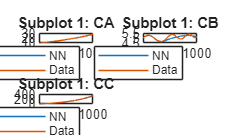

%%%%%%RESULT VALIDATION: Explicit Euler:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1:3, :) = C(1:3, :);
for i = 2:(occurences-2)
    fNN(i+1,:) = fNN(i,:) + dt(i) .* predict(modelNN2, fNN(i,:));
end %for

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

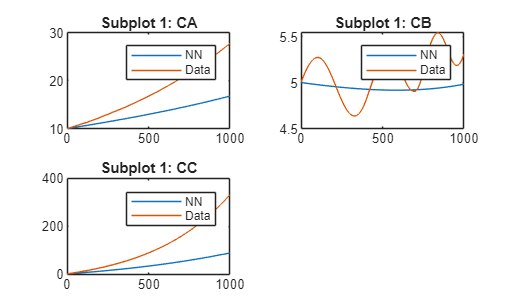

%%%%%%RESULT VALIDATION: FORWARD PASS:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1, :) = C(1, :);
numLayers = size(arraySize, 2);
for i = 1:(occurences-1)
    zk = fNN(i, :)';
    for j = 1:numLayers
        zk = modelNN2.LayerWeights{j} * zk + modelNN2.LayerBiases{j};
        zk = max(0, zk);
    end %for
    zk = modelNN2.LayerWeights{numLayers+1} * zk + modelNN2.LayerBiases{numLayers+1};
    
    fNN(i+1, :) = fNN(i, :) + dt(i) .* zk';
end %for 

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(C, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')

%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 